% MATLAB Code to Import Processed Data and Generate Plots
% Load the processed CSV file
filename = 'Randle_circuit_processed.csv';
data = readtable(filename);


% Display the table variable names to verify column headers
disp(data.Properties.VariableNames);

    {'Frequency'}    {'Magnitude_dB_'}    {'Phase_deg_'}    {'Magnitude_linear_'}



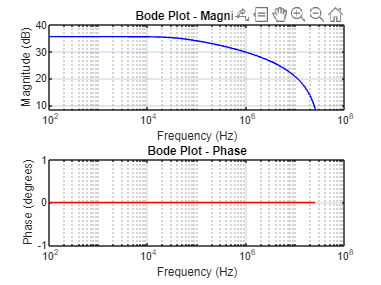


% Access the correct columns dynamically (replace with actual column names after verification)
frequency = data{:, data.Properties.VariableNames{1}};           % Frequency in Hz
magnitude_linear = data{:, data.Properties.VariableNames{2}};    % Magnitude in linear scale
phase_deg = data{:, data.Properties.VariableNames{3}};           % Phase in degrees

% Generate the Bode plot
figure;
subplot(2, 1, 1);
semilogx(frequency, 20*log10(magnitude_linear), 'b'); % Magnitude in dB
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Bode Plot - Magnitude');
grid on;

subplot(2, 1, 2);
semilogx(frequency, phase_deg, 'r'); % Phase in degrees
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('Bode Plot - Phase');
grid on;

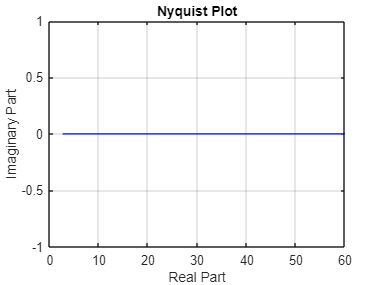


% Generate the Nyquist plot
figure;
real_part = magnitude_linear .* cosd(phase_deg);
imag_part = magnitude_linear .* sind(phase_deg);
plot(real_part, imag_part, 'b');
xlabel('Real Part');
ylabel('Imaginary Part');
title('Nyquist Plot');
grid on;